clc;
clear;
close all;

s = tf('s');

% Drone transfer function
G = 1/(s^2 + 2*s + 5);

% Display poles
p = pole(G)

p =   -1.0000 + 2.0000i
  -1.0000 - 2.0000i


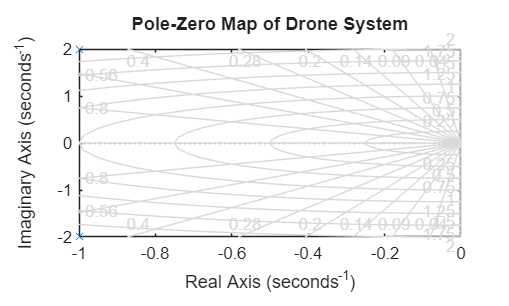


% Plot pole-zero map
figure;
pzmap(G);
grid on;
title('Pole-Zero Map of Drone System');


% Stability check
if all(real(p) < 0)
    disp('System is STABLE');
elseif any(real(p) > 0)
    disp('System is UNSTABLE');
else
    disp('System is MARGINALLY STABLE');
end

System is STABLE
